%% データの読み込み
sub = 10; % 被験者の指定
filename = ['../../../materials/alpha_data_tsss/' 'sub' num2str(sub) '_alpha_data_tsss'];
dummy = ['load ' filename ' data_*'];
eval(dummy);

%% データの分割
cfg = [];
cfg.length = 2; % 2秒の時間窓
cfg.overlap = 0.5; % 時間窓のオーバーラップの割合 (この場合2秒*0.5=1秒)
data_o_crop = ft_redefinetrial(cfg, data_o);

the input is raw data with 204 channels and 6 trials
the input is raw data with 204 channels and 6 trials
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_redefinetrial" took 1 seconds


data_c_crop = ft_redefinetrial(cfg, data_c);

the input is raw data with 204 channels and 6 trials
the input is raw data with 204 channels and 6 trials
the call to "ft_redefinetrial" took 1 seconds
the call to "ft_redefinetrial" took 1 seconds


%% FFT
cfg = [];
cfg.method = 'mtmfft';
cfg.taper = 'hanning';
cfg.output = 'pow';
cfg.keeptrials = 'yes'

cfg = フィールドをもつ struct :
        method: 'mtmfft'
         taper: 'hanning'
        output: 'pow'
    keeptrials: 'yes'


FFT_o = ft_freqanalysis(cfg, data_o_crop);

the input is raw data with 204 channels and 174 trials
the call to "ft_selectdata" took 0 seconds
Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
processing trial 174/174 nfft: 2000 samples, datalength: 2000 samples, 1 tapers

the call to "ft_freqanalysis" took 8 seconds


FFT_c = ft_freqanalysis(cfg, data_c_crop)

the input is raw data with 204 channels and 174 trials
the call to "ft_selectdata" took 0 seconds
Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
processing trial 174/174 nfft: 2000 samples, datalength: 2000 samples, 1 tapers

the call to "ft_freqanalysis" took 8 seconds


FFT_c = フィールドをもつ struct :
        label: {204×1 cell}
       dimord: 'rpt_chan_freq'
         freq: [0 0.5000 1 1.5000 2 2.5000 3 3.5000 4 4.5000 5 5.5000 6 6.5000 7 7.5000 8 8.5000 9 9.5000 10 10.5000 11 11.5000 12 12.5000 13 13.5000 14 14.5000 15 15.5000 16 16.5000 17 17.5000 18 18.5000 19 19.5000 20 20.5000 21 … ] (1×1001 double)
    powspctrm: [174×204×1001 double]
    cumsumcnt: [174×1 double]
    cumtapcnt: [174×1 double]
         grad: [1×1 struct]
          cfg: [1×1 struct]


cfg = [];
cfg.channel = {'MEGGRAD'};
cfg.combinemethod = 'sum';
FFT_o_cmb = ft_combineplanar(cfg, FFT_o);

the input is freq data with 204 channels, 1001 frequencybins and no timebins


the call to "ft_combineplanar" took 0 seconds


FFT_c_cmb = ft_combineplanar(cfg, FFT_c);

the input is freq data with 204 channels, 1001 frequencybins and no timebins


the call to "ft_combineplanar" took 0 seconds


Target_ch_o=[72 79	78	74	62	77	90	71	73	75];
Target_ch_c=[78	77	75	79	72	74	69	76	90	71];

%% 等磁界線図のためのパラメータ設定
cfg = [];
cfg.marker = 'on'; % センサの位置を表示
cfg.layout = 'neuromag306cmb'; % 今回のデータのMEGシステムを指定
cfg.xlim = [8 13]; % 8-13 Hzの平均パワーをプロット
cfg.colorbar = 'yes'; % スケールバーを表示
cfg.figure = 'gcf';
cfg.highlight = 'on'; % スペクトル計算に用いたセンサをハイライト
cfg.highlightcolor = [1 0 0]; % ハイライトの色を赤に設定
%% 上段左に開眼時，右に閉眼時の等磁界線図をプロット

aveFFT_o=zeros(size(FFT_o_cmb.powspctrm, 1), 1);
aveFFT_c=zeros(size(FFT_c_cmb.powspctrm, 1), 1);
for i = 1:size(FFT_o_cmb.powspctrm,1)
    %% 選択されたセンサにわたって平均したパワースペクトルを描画
    aveFFT_o(i) = mean(mean(FFT_o_cmb.powspctrm(i,Target_ch_o,8<FFT_o_cmb.freq&FFT_o_cmb.freq<13)))*10^26; % [T 2 /m 2 Hz] -> [fT 2 /cm 2 Hz]
    aveFFT_c(i) = mean(mean(FFT_c_cmb.powspctrm(i,Target_ch_c,8<FFT_c_cmb.freq&FFT_c_cmb.freq<13)))*10^26; % [T 2 /m 2 Hz] -> [fT2 /cm 2 Hz]
end
aveFFT_o

aveFFT_o = 1.0e+03 *

    0.0260
    0.0323
    0.0390
    0.0312
    0.0356
    0.0427
    0.0258
    0.0274
    0.0393
    0.0331


aveFFT_c

aveFFT_c = 1.0e+03 *

    1.3916
    1.5105
    1.3579
    1.1732
    1.3988
    0.7212
    0.5841
    0.7056
    1.1087
    1.1664


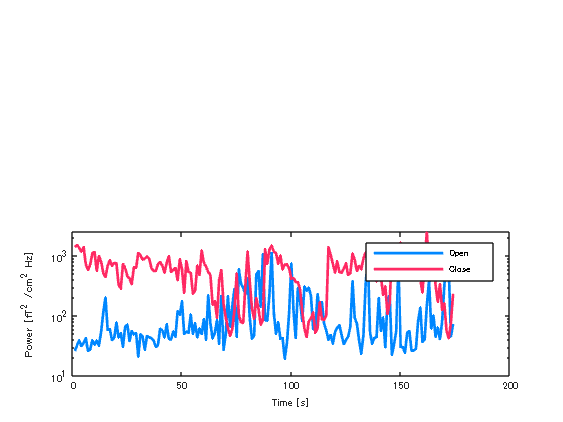

hold off;
subplot(2,1,2)
semilogy(aveFFT_o,'Color',[0,135,255]/255,'LineWidth', 2);
hold on;
semilogy(aveFFT_c,'Color',[255,42,99]/255,'LineWidth', 2);
legend('Open', 'Close')
xlabel('Time [s]');
ylabel('Power [fT^2 /cm^2 Hz]');
hold off;